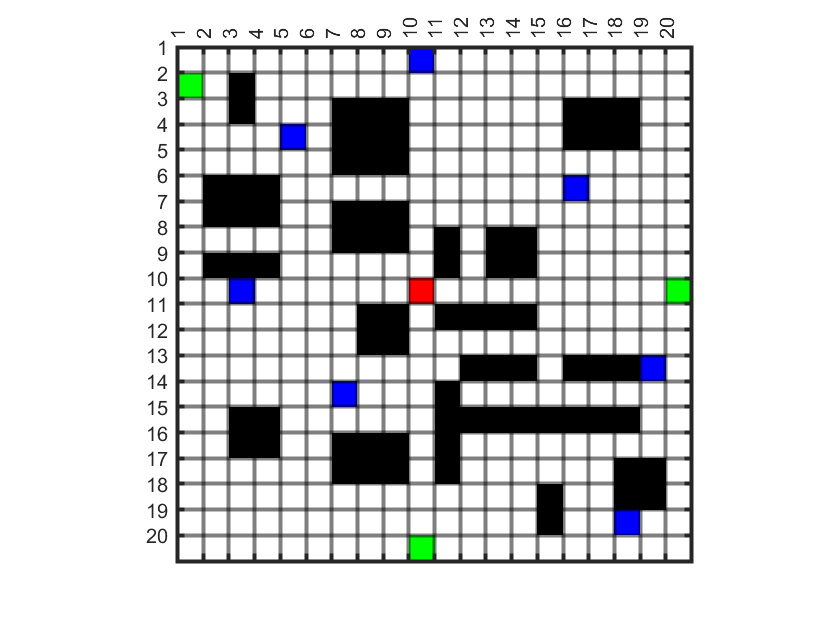

%% 构建颜色MAP图
clc;clear;
cmap = [1 1 1;...  % 1-白色-空地
    0 0 0;...  % 2-黑色-障碍物
    0 1 1;...  % 3-青蓝色-start_pos
    1 0 0;...  % 4-红色-goal_pos
    0 1 0;...  % 5-绿色
    0 0 1;...  % 6-蓝色
    1 1 0;...  % 7-黄色
    1 0 1];...  % 8-品红色
% 构建颜色MAP图
colormap(cmap);

Grid=  [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 1 0 0 0 1 1 1 0 0 0 0 0 0 1 1 1 0 0;
     0 0 0 0 0 0 1 1 1 0 0 0 0 0 0 1 1 1 0 0;
     0 0 0 0 0 0 1 1 1 0 0 0 0 0 0 0 0 0 0 0;
     0 1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
     0 1 1 1 0 0 1 1 1 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 1 1 1 0 1 0 1 1 0 0 0 0 0 0;
     0 1 1 1 0 0 0 0 0 0 1 0 1 1 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 1 1 0 1 1 1 1 0 0 0 0 0 0;
     0 0 0 0 0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 1 1 1 0 1 1 1 0 0;
     0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0;
     0 0 1 1 0 0 0 0 0 0 1 1 1 1 1 1 1 1 0 0;
     0 0 1 1 0 0 1 1 1 0 1 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 1 1 1 0 1 0 0 0 0 0 0 1 1 0; 
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 1 1 0;
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];


% 起始点和目标点
row_grid = size(Grid,1);
col_grid = size(Grid,2);
numb_grid = row_grid*col_grid;
startPos = sub2ind([size(Grid,1),size(Grid,2)],10,10);
goalPos1 = 2;
goalPos2 = sub2ind([size(Grid,1),size(Grid,2)],20,10);
goalPos3 = sub2ind([size(Grid,1),size(Grid,2)],10,20);
goalPos = [goalPos1,goalPos2,goalPos3];
Grid(startPos) = 3;
Grid(goalPos) = 4;
stopPos1 = sub2ind([size(Grid,1),size(Grid,2)],1,10);
stopPos2 = sub2ind([size(Grid,1),size(Grid,2)],4,5);
stopPos3 = sub2ind([size(Grid,1),size(Grid,2)],10,3);
stopPos4 = sub2ind([size(Grid,1),size(Grid,2)],14,7);
stopPos5 = sub2ind([size(Grid,1),size(Grid,2)],6,16);
stopPos6 = sub2ind([size(Grid,1),size(Grid,2)],13,19);
stopPos7 = sub2ind([size(Grid,1),size(Grid,2)],19,18);
stopPos = [stopPos1,stopPos2,stopPos3,stopPos4,stopPos5,stopPos6,stopPos7];
Grid(stopPos) = 5;
%% 画栅格图
image(1.5,1.5,Grid+1);
grid on;
set(gca,'gridline','-','gridcolor','k','linewidth',2,'GridAlpha',0.5);% 设置网格为：网格线实线、颜色黑色、线宽2、透明度0.5；
set(gca, 'XTick', 1:size(Grid,1), 'YTick', 1:size(Grid,2)); ;% 设置网格为长宽高为一样的正方形
axis image;
set(gca,'xAxisLocation','top')